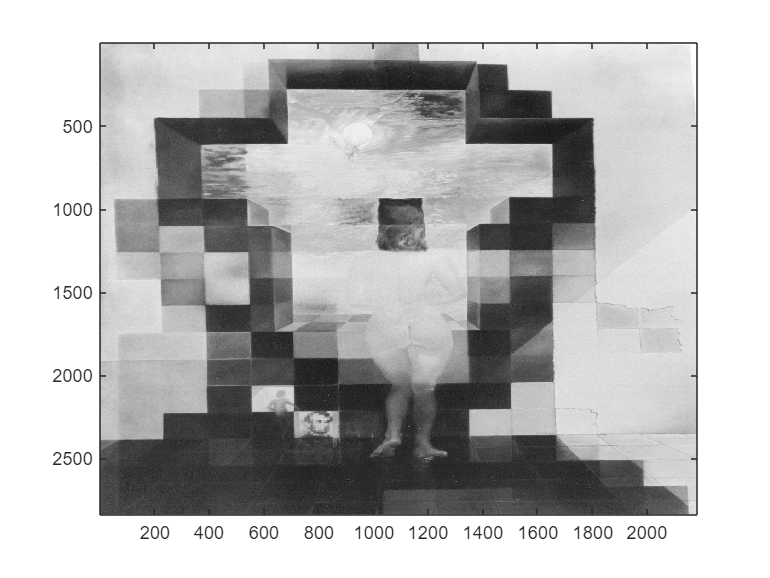

gala = double(rgb2gray(imread("gala-desnuda-mirando.jpg")));
[h,w] = size(gala);
imagesc(gala)
colormap('gray')

% Dimensiones
cm = 1e-2;
mm = 1e-3;
um = 1e-6;
nm = 1e-9;

lambda = 600*nm;

z = 1e3;

% Ojo humano

diametroPupila = 4*mm; % En promedio

distanciaFovea = 2.5*cm; % Diametro promedio del ojo


% Gala desnuda mirando 
alto = 4.2;
ancho = 3.18;

dx = ancho/w;
dy = alto/h;

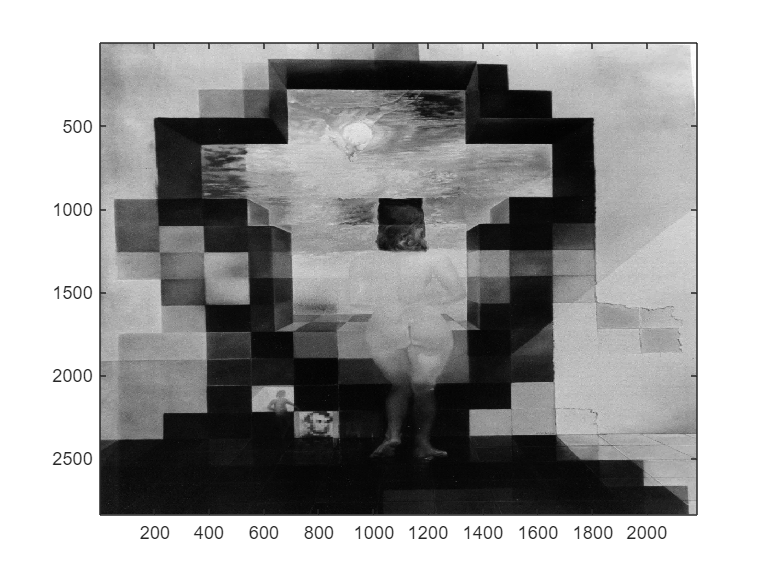

% Propagacion

prop = espectroAngular(gala,dx,dy,z,lambda);

imagesc(abs(prop).^2)

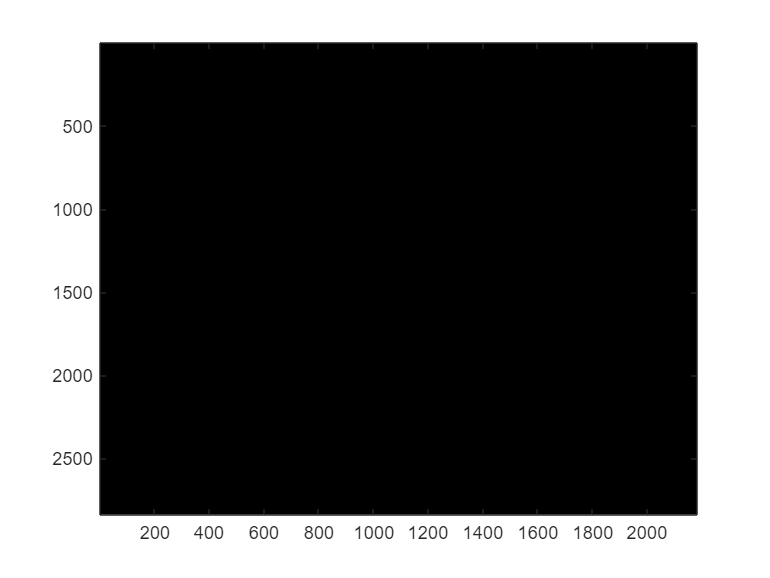

% Pupila
radioPupila = (diametroPupila/2)/dx;

pupila = filtroCircular([w/2 round(h/2)],radioPupila,[h w]);
imagesc(pupila)